# Run Param_lab3_real.mlx

## Run General parameter

Tw_awu = ts_5/5;
Kw_awu = 1/Tw_awu;

## Set step amplitude 50 deg

step_amplitude = 50;

# Simulate value with windup filter step 50 [deg] (lab3_windup_sim_real) o box

## Salva dati no antiwind up 50 deg

t = out.ScopeData1.time;
tetha = out.ScopeData1.signals(1).values;  
ref = out.ScopeData1.signals(2).values;
error = out.ScopeData1.signals(3).values;
command_u =  out.ScopeData1.signals(4).values;

save("windup_data_lab3_50_real_lab3.mat",'t','tetha','ref','error','command_u');


# Simulate value with antiwindup filter step 50 [deg] (lab3_antiwindup_sim_real) o box

## Salva dati antiwind up 50 deg

t1 = out.ScopeData1.time;
tetha1 = out.ScopeData1.signals(1).values;  
ref1 = out.ScopeData1.signals(2).values;
error1 = out.ScopeData1.signals(3).values;
command_u1 =  out.ScopeData1.signals(4).values;

save("antiwindup_data_lab3_50_real_lab3.mat",'t1','tetha1','ref1','error1','command_u1');

## Set step amplitude120 deg

step_amplitude = 120;

# Simulate value with windup filter step 120 [deg] (lab3_windup_sim_real) o box

## Salva dati no antiwind up 120 deg


t2 = out.ScopeData1.time;
tetha2 = out.ScopeData1.signals(1).values;  
ref2 = out.ScopeData1.signals(2).values;
error2 = out.ScopeData1.signals(3).values;
command_u2 =  out.ScopeData1.signals(4).values;

save("windup_data_lab3_120_real_lab3.mat",'t2','tetha2','ref2','error2','command_u2');


# Simulate value with antiwindup filter step 120 [deg] (lab3_antiwindup_sim_real) o box

## Salva dati with antiwind up 120 deg


t3 = out.ScopeData1.time;
tetha3 = out.ScopeData1.signals(1).values;  
ref3 = out.ScopeData1.signals(2).values;
error3 = out.ScopeData1.signals(3).values;
command_u3 =  out.ScopeData1.signals(4).values;

save("antiwindup_data_lab3_120_real_lab3.mat",'t1','tetha1','ref1','error1','command_u1');


## Stampa grafici

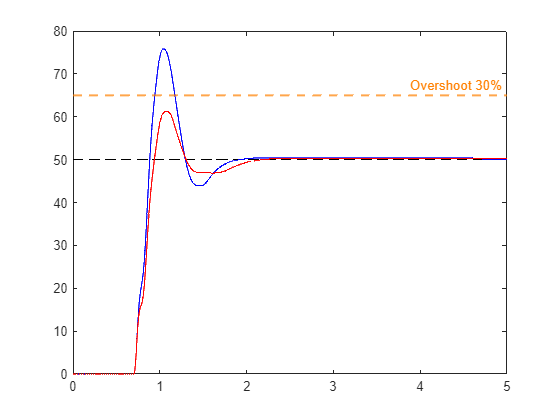


% grafico step 50 deg

load("windup_data_lab3_50_real_lab3.mat");
load("antiwindup_data_lab3_50_real_lab3.mat");
figure;
plot(t,ref,'k--');
yline(65, '--', 'Color', '[1, 0.5, 0]', 'LineWidth', 1.5, 'Label', 'Overshoot 30%');
hold on 
plot(t,tetha,'b');
plot(t1,tetha1,'r');
axis([0 5 0 80])
hold off

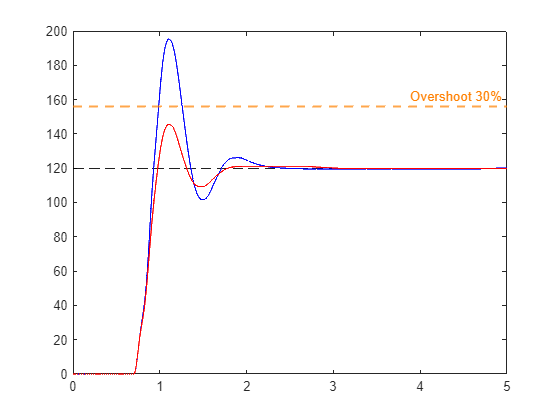


load("windup_data_lab3_120_real_lab3.mat");
load("antiwindup_data_lab3_120_real_lab3.mat");

% grafico step 120 deg

figure;
plot(t2,ref2,'k--');

hold on 
yline(156, '--', 'Color', '[1, 0.5, 0]', 'LineWidth', 1.5, 'Label', 'Overshoot 30%');
plot(t2,tetha2,'b');
plot(t3,tetha3,'r');
axis([0 5 0 200])
hold off

#### Step response parameters

% Calcolo dei dati mantenendo i tuoi nomi originali
step_50_wind_up = stepinfo(tetha, t, 50, 'SettlingTimeThreshold', 0.05);
step_50_anti_wind_up = stepinfo(tetha1, t1, 50, 'SettlingTimeThreshold', 0.05);
step_120_wind_up = stepinfo(tetha2, t2, 120, 'SettlingTimeThreshold', 0.05);
step_120_anti_wind_up = stepinfo(tetha3, t3, 120, 'SettlingTimeThreshold', 0.05);

% Raccolta dei risultati in un array di strutture
results = [step_50_wind_up; step_50_anti_wind_up; step_120_wind_up; step_120_anti_wind_up];

% Conversione in tabella
T = struct2table(results);

% Aggiunta dei nomi delle righe per chiarezza
T.Properties.RowNames = {
    'step_50_wind_up', ...
    'step_50_anti_wind_up', ...
    'step_120_wind_up', ...
    'step_120_anti_wind_up'
};

% Visualizzazione della tabella

disp(T(:, {'RiseTime', 'SettlingTime', 'Overshoot'}))

                             RiseTime    SettlingTime    Overshoot
                             ________    ____________    _________

    step_50_wind_up          0.14293         1.949         51.56  
    step_50_anti_wind_up     0.18082         2.056          22.4  
    step_120_wind_up          0.1668          2.22         62.75  
    step_120_anti_wind_up    0.20197        1.9199         21.35  

